In this homework assignment a Kohonen Self-Organizing Map (SOM) will be trained on MNIST dataset and the resulting weights of the network (centroids) will be dispalyed as images.

clc; clear; close all;
load('HW11_code_workspace.mat');

# 0. MNIST Dataset

## 0.1 Downloading MNIST Dataset and Import into *Matlab*

The code snippet below will download MNIST dataset from web and extract the downloaded files into Matlab matrices as test and train images and labels.

mnist_train_image = 'train-images-idx3-ubyte';
mnist_train_label = 'train-labels-idx1-ubyte';
mnist_test_image  = 't10k-images-idx3-ubyte';
mnist_test_label  = 't10k-labels-idx1-ubyte';
train_set_number  = 60000;
test_set_number   = 10000;

downloadMNIST(mnist_train_image, mnist_train_label, mnist_test_image, mnist_test_label);

Error using matlab.internal.webservices.HTTPConnector/copyContentToFile (line 412)
Web service operation terminated by user while accessing URL 'http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz'.

Error in websave (

[train_images, train_labels] = readMNIST(mnist_train_image, mnist_train_label, train_set_number);
[test_images,   test_labels] = readMNIST(mnist_test_image, mnist_test_label, test_set_number);

clear mnist_train_image mnist_train_label mnist_test_image mnist_test_label train_set_number test_set_number

## 0.2 Plotting a Sample of MNIST Dataset

A set of 100 randomly chosen samples of the training dataset is plotted here.

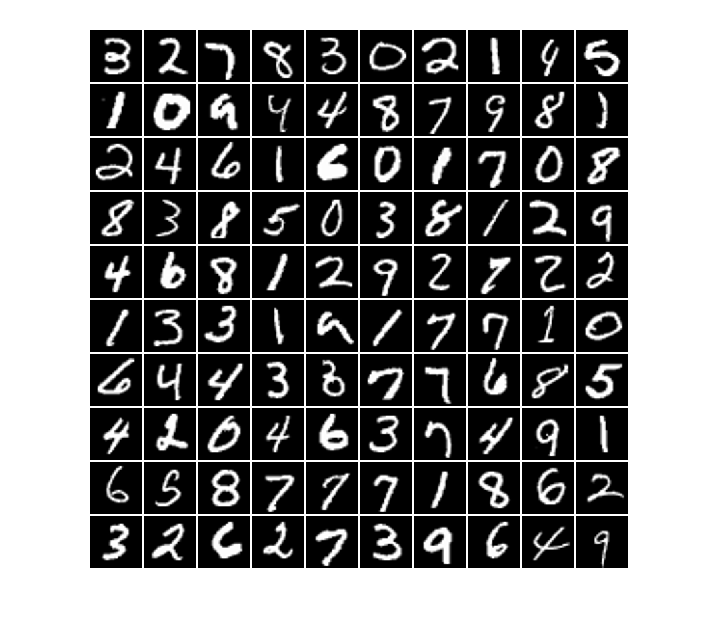

random_indices = randi(60000, [1 100]);
montage(train_images(:, :, random_indices), 'BorderSize', [2 2], 'BackgroundColor', 'white');

## 0.3 Number of Occurances for Each Digit in Training Set

Here we investigate how many of each digit is there in the training set.

for i=0:9
    disp([num2str(i),': ', num2str(sum(train_labels == i))]);
end

0: 5923
1: 6742
2: 5958
3: 6131
4: 5842
5: 5421
6: 5918
7: 6265
8: 5851
9: 5949


# 1,2. Training Kohonen SOM

## 1,2.1 Reshaping the Training images

The images should be reshaped from 28x28 images to vectors of 784 elements, so they could be fed into our neural network.

train_images_reshaped = reshape(train_images, [size(train_images, 1)*size(train_images, 2) size(train_images, 3)]);

## 1,2.2 Defining the Network

The Self-Organizing Map (SOM) charactersitics are defined as below:

- SOM's number of output neurons is 40.

- The network will be trained for 2000 epochs on the whole training set of MNIST and the neighborhood size will be shrinked to 1 on the 1000th epoch and maintained 1 for the rest of training process.

- Initial number of neighbors for each neuron (window size) is set to 31.

- The som output is distributed on line (1-D).

net = selforgmap(40, 1000, 31, 'gridtop', 'dist');
net.trainParam.showCommandLine = true;
net = configure(net, train_images_reshaped);

The SOM block diagram is shown below.

view(net);

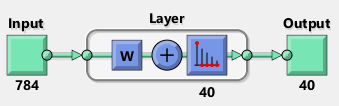

## 1,2.2 Training the Network

Training process is started here and will perform for 2000 epochs on the whole training set of MNIST.

[net, tr] = train(net, train_images_reshaped, 'showResources', 'yes');

Calculation mode: MATLAB
 
Training Self-Organizing Map with TRAINBU.
Epoch 0/2000, Time 8.554
Epoch 25/2000, Time 197.912
Epoch 50/2000, Time 388.029
Epoch 75/2000, Time 578.313
Epoch 100/2000, Time 768.036
Epoch 125/2000, Time 957.678
Epoch 150/2000, Time 1147.487
Epoch 175/2000, Time 1328.154
Epoch 200/2000, Time 1503.661
Epoch 225/2000, Time 1679.494
Epoch 250/2000, Time 1870.152
Epoch 275/2000, Time 2059.483
Epoch 300/2000, Time 2249.092
Epoch 325/2000, Time 2438.753
Epoch 350/2000, Time 2626.825
Epoch 375/2000, Time 2813.981
Epoch 400/2000, Time 3002.164
Epoch 425/2000, Time 3178.537
Epoch 450/2000, Time 3351.311
Epoch 475/2000, Time 3527.981
Epoch 500/2000, Time 3715.781
Epoch 525/2000, Time 3907.704
Epoch 550/2000, Time 4100.043
Epoch 575/2000, Time 4284.706
Epoch 600/2000, Time 4467.254
Epoch 625/2000, Time 4658.501
Epoch 650/2000, Time 4851.395
Epoch 675/2000, Time 5043.137
Epoch 700/2000, Time 5234.683
Epoch 725/2000, Time 5428.209
Epoch 750/2000, Time 5621.437
Epoch 775/200

# 3. Displaying 40 Centroids

## 3.1 Saving Weights for Further Use

Every neuron in the output layer will have a set of weights of 784 elements. We will save and reshape them in images of 28x28 size.

weights = net.IW{1}';
weights_reshaped = reshape(weights, [28 28 40]);

## 3.2 Plotting Weights (Centroids)

The whole training dataset is mapped into 40 neurons. Here we have plotted the centroids. A number above every centroid represents the number of images of the training dataset which are mapped into that specific centroid.

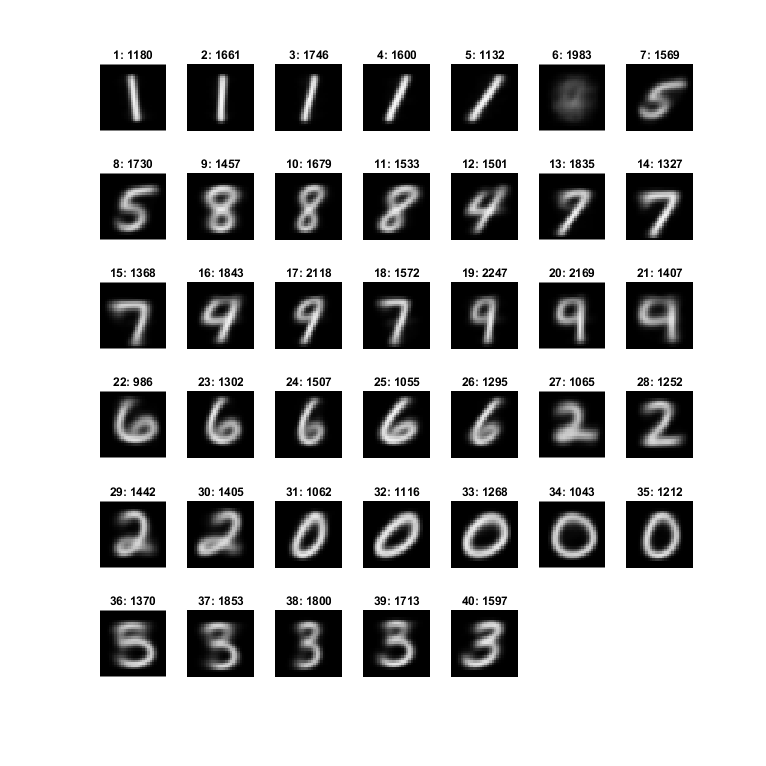

y = net(train_images_reshaped);
map_results = sum(y, 2);

figure('Position', [1, 1, 1000, 1000]);
for i = 1:40
    subplot(6, 7, i);
    imshow(weights_reshaped(:, :, i));
    t = sprintf('%d: %d', i, map_results(i));
    title(t);
    hold on;
end
hold off

# Appendix

## A.1 Saving Workspace Variables for Future Use 

save('HW11_code_workspace.mat');

## A.2 Defiition of Auxiliary Functions

function downloadMNIST(mnist_train_image, mnist_train_label, mnist_test_image, mnist_test_label)

if exist('train-images-idx3-ubyte','file') ~= 2
    disp('Downloading MNIST dataset...');
    websave([mnist_train_image,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_train_image, '.gz']);
    websave([mnist_train_label,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_train_label, '.gz']);
    websave([mnist_test_image,'.gz'],...    
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_test_image, '.gz']);
    websave([mnist_test_label,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_test_label, '.gz']);
    disp('MNIST dataset downloded.');
    
    disp('Unzipping started...');
    gunzip([mnist_train_image, '.gz'])
    gunzip([mnist_train_label, '.gz'])
    gunzip([mnist_test_image, '.gz'])
    gunzip([mnist_test_label, '.gz'])
    delete([mnist_train_image, '.gz'])
    delete([mnist_train_label, '.gz'])
    delete([mnist_test_image, '.gz'])
    delete([mnist_test_label, '.gz'])
    disp('Unzipping completed.');
else
    disp('MNIST dataset already downloaded.')
end

end

function [imgs, labels] = readMNIST(imgFile, labelFile, num_of_digits_to_read)

fileID = fopen(imgFile, 'r', 'b');
header = fread(fileID, 1, 'int32');

if header ~= 2051
    error('Invalid image file header');
end

count = fread(fileID, 1, 'int32');

if count < num_of_digits_to_read
    error('Trying to read too many digits');
end

rows_num = fread(fileID, 1, 'int32');
cols_num = fread(fileID, 1, 'int32');

imgs = zeros([rows_num cols_num num_of_digits_to_read]);

for i = 1:num_of_digits_to_read
    for row = 1:rows_num
        imgs(row, :, i) = fread(fileID, cols_num, 'uint8');
    end
end

fclose(fileID);

fileID = fopen(labelFile, 'r', 'b');
header = fread(fileID, 1, 'int32');

if header ~= 2049
    error('Invalid label file header');
end

count = fread(fileID, 1, 'int32');

if count < num_of_digits_to_read
    error('Trying to read too many digits');
end

labels = fread(fileID, num_of_digits_to_read, 'uint8');

fclose(fileID);

imgs = double(imgs)./255.0;

end

function iMontage(images)
montage(reshape(images, [28 28 size(images, 2)]), 'BackgroundColor', 'white', 'BorderSize', [2 2]);
end

function display_original_images_vs_reconstructed(original_images, reconstructed_images)
figure('Position', [100, 100, 1000, 500]);
subplot(1, 2, 1);
iMontage(original_images);
title('Original Images');
hold on;
subplot(1, 2, 2);
iMontage(reconstructed_images);
title('Reconstructed Images')
hold off
end

function categorized_label = iCategorical(on_hot_encoded_label)
[ind, ~]= vec2ind(on_hot_encoded_label);
categorized_label = categorical(ind', 1:10, {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'});
end




function saveMNISTasFolderOfImages(outputPath, train_images, train_labels, test_images, test_labels)

if(~isempty(outputPath))
    assert(exist(outputPath,'dir') == 7);
end

% Set names for directories
trainDirectoryName = 'mnistTrain';
testDirectoryName = 'mnistTest';

% Create directories for the output
mkdir(fullfile(outputPath, trainDirectoryName));
mkdir(fullfile(outputPath, testDirectoryName));

labelNames = {'0','1','2','3','4','5','6','7','8','9'};
iMakeTheseDirectories(fullfile(outputPath, trainDirectoryName), labelNames);
iMakeTheseDirectories(fullfile(outputPath, testDirectoryName), labelNames);


iLoadBatchAndWriteAsImagesToLabelFolders(train_images, fullfile(outputPath, trainDirectoryName), labelNames, train_labels);

iLoadBatchAndWriteAsImagesToLabelFolders(test_images, fullfile(outputPath, testDirectoryName), labelNames, test_labels);

end

function iLoadBatchAndWriteAsImagesToLabelFolders(data, fullOutputDirectoryPath, labelNames, labels)
for i = 1:size(data,3)
    imwrite(data(:,:,i), fullfile(fullOutputDirectoryPath, labelNames{labels(i)+1}, ['image' num2str(i) '.png']));
end
end

function iMakeTheseDirectories(outputPath, directoryNames)
for i = 1:numel(directoryNames)
    mkdir(fullfile(outputPath, directoryNames{i}));
end
end
